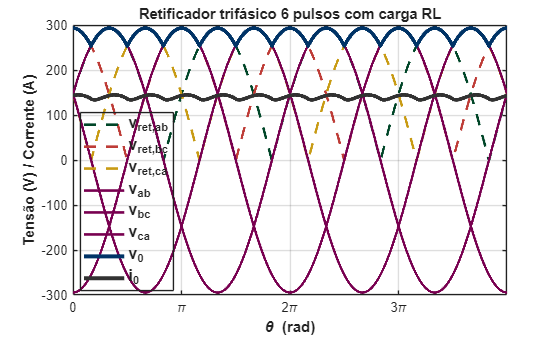

%% Retificador trifásico 6 pulsos (ponte de diodos) + carga RL

clear; clc;

f   = 60;
Vm  = 170;
R   = 2;
L   = 1e-3;
Vd  = 0.7;
ncy = 12;
fs  = 200e3;

plotCycles = [10 11];

T     = 1/f;
dt    = 1/fs;
t     = 0:dt:(ncy*T);
omega = 2*pi*f;
theta = omega*t;

v_a = Vm*sin(theta);
v_b = Vm*sin(theta - 2*pi/3);
v_c = Vm*sin(theta + 2*pi/3);

v_ab = v_a - v_b;
v_bc = v_b - v_c;
v_ca = v_c - v_a;

v_rect_ab = max(abs(v_ab) - 2*Vd, 0);
v_rect_bc = max(abs(v_bc) - 2*Vd, 0);
v_rect_ca = max(abs(v_ca) - 2*Vd, 0);

v_0 = max([v_rect_ab; v_rect_bc; v_rect_ca], [], 1);

i_0 = zeros(size(t));
for k = 2:numel(t)
    di_dt = (v_0(k) - R*i_0(k-1))/L;
    i_0(k) = i_0(k-1) + di_dt*dt;
    if i_0(k) < 0, i_0(k) = 0; end
end

statale.maincolor = [0   51  102]/255;
statale.lilla     = [120 0   80 ]/255;
statale.darkgreen = [0   70  40 ]/255;
statale.red       = [190 60  55 ]/255;
statale.yellow    = [200 155 20 ]/255;
statale.grey      = [50 50 50]/255;

plotColors = [statale.maincolor; statale.lilla; statale.darkgreen; statale.red; statale.yellow];
set(groot,'defaultAxesColorOrder',plotColors);

LW  = 3.0;
LW2 = 2;
LW3 = 3;

c1 = plotCycles(1);
c2 = plotCycles(2);

t1 = (c1-1)*T;
t2 = c2*T;

idx = (t >= t1) & (t <= t2);

thetaP   = theta(idx);
thetaRel = thetaP - thetaP(1);

vabP = v_ab(idx);  vbcP = v_bc(idx);  vcaP = v_ca(idx);
vraP = v_rect_ab(idx); vrbP = v_rect_bc(idx); vrcP = v_rect_ca(idx);

v0P  = v_0(idx);
i0P  = i_0(idx);

figure('Color','w');

plot(thetaRel, vraP, '--', 'Color', plotColors(3,:), 'LineWidth', LW2); hold on;
plot(thetaRel, vrbP, '--', 'Color', plotColors(4,:), 'LineWidth', LW2);
plot(thetaRel, vrcP, '--', 'Color', plotColors(5,:), 'LineWidth', LW2);

plot(thetaRel, vabP, 'Color', plotColors(2,:), 'LineWidth', LW2);
plot(thetaRel, vbcP, 'Color', plotColors(2,:), 'LineWidth', LW2);
plot(thetaRel, vcaP, 'Color', plotColors(2,:), 'LineWidth', LW2);

plot(thetaRel, v0P, 'Color', plotColors(1,:), 'LineWidth', LW3);
plot(thetaRel, i0P, 'Color', statale.grey, 'LineWidth', LW3);

grid on;
xlabel('\theta (rad)');
ylabel('Tensão (V) / Corrente (A)');
title('Retificador trifásico 6 pulsos com carga RL');

xlim([0, thetaRel(end)]);
k2 = floor(thetaRel(end)/pi);
xt = (0:k2)*pi;
xticks(xt);

m = 0:k2;
labs = strings(size(m));
for kk = 1:numel(m)
    if m(kk) == 0
        labs(kk) = "0";
    elseif m(kk) == 1
        labs(kk) = "\pi";
    else
        labs(kk) = sprintf('%g\\pi', m(kk));
    end
end
xticklabels(labs);

lgd = legend('v_{ret,ab}','v_{ret,bc}','v_{ret,ca}', ...
             'v_{ab}','v_{bc}','v_{ca}', ...
             'v_0','i_0', 'Location','best');
lgd.FontSize   = 12;
lgd.FontWeight = 'bold';
lgd.Color      = 'none';

ax = gca;
ax.XLabel.FontWeight = 'bold';
ax.YLabel.FontWeight = 'bold';

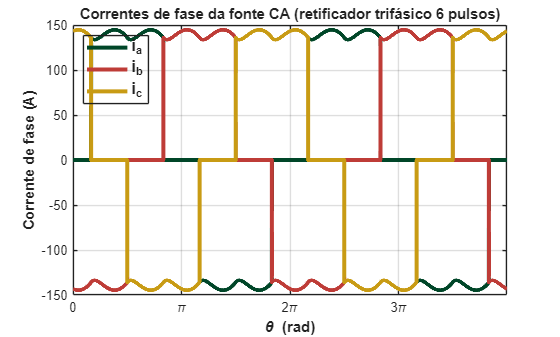


Vmat = [v_a; v_b; v_c];
[~, idxMax] = max(Vmat, [], 1);
[~, idxMin] = min(Vmat, [], 1);

i_a = zeros(size(t));
i_b = zeros(size(t));
i_c = zeros(size(t));

i_a(idxMax==1) =  i_0(idxMax==1);
i_a(idxMin==1) = -i_0(idxMin==1);

i_b(idxMax==2) =  i_0(idxMax==2);
i_b(idxMin==2) = -i_0(idxMin==2);

i_c(idxMax==3) =  i_0(idxMax==3);
i_c(idxMin==3) = -i_0(idxMin==3);

iaP = i_a(idx);
ibP = i_b(idx);
icP = i_c(idx);

figure('Color','w');
plot(thetaRel, iaP, 'Color', plotColors(3,:), 'LineWidth', LW); hold on;
plot(thetaRel, ibP, 'Color', plotColors(4,:), 'LineWidth', LW);
plot(thetaRel, icP, 'Color', plotColors(5,:), 'LineWidth', LW);
grid on;

xlabel('\theta (rad)');
ylabel('Corrente de fase (A)');
title('Correntes de fase da fonte CA (retificador trifásico 6 pulsos)');

xlim([0, thetaRel(end)]);
xticks(xt);
xticklabels(labs);

lgd2 = legend('i_a','i_b','i_c', 'Location','best');
lgd2.FontSize   = 12;
lgd2.FontWeight = 'bold';
lgd2.Color      = 'none';

ax2 = gca;
ax2.XLabel.FontWeight = 'bold';
ax2.YLabel.FontWeight = 'bold';

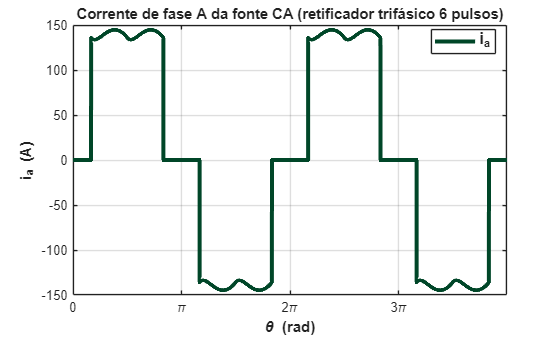


figure('Color','w');
plot(thetaRel, iaP, 'Color', plotColors(3,:), 'LineWidth', LW); hold on;
grid on;

xlabel('\theta (rad)');
ylabel('i_a (A)');
title('Corrente de fase A da fonte CA (retificador trifásico 6 pulsos)');

xlim([0, thetaRel(end)]);
xticks(xt);
xticklabels(labs);

lgdA = legend('i_a','Location','best');
lgdA.FontSize   = 12;
lgdA.FontWeight = 'bold';
lgdA.Color      = 'none';

axA = gca;
axA.XLabel.FontWeight = 'bold';
axA.YLabel.FontWeight = 'bold';

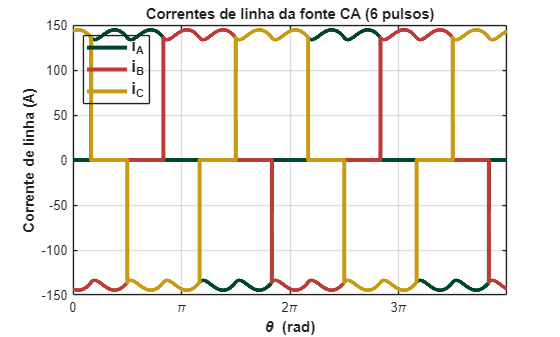


figure('Color','w');
plot(thetaRel, iaP, 'Color', plotColors(3,:), 'LineWidth', LW); hold on;
plot(thetaRel, ibP, 'Color', plotColors(4,:), 'LineWidth', LW);
plot(thetaRel, icP, 'Color', plotColors(5,:), 'LineWidth', LW);
grid on;

xlabel('\theta (rad)');
ylabel('Corrente de linha (A)');
title('Correntes de linha da fonte CA (6 pulsos)');

xlim([0, thetaRel(end)]);
xticks(xt); xticklabels(labs);

lgd = legend('i_A','i_B','i_C','Location','best');
lgd.FontSize = 12; lgd.FontWeight = 'bold'; lgd.Color = 'none';
ax = gca; ax.XLabel.FontWeight='bold'; ax.YLabel.FontWeight='bold';